# Machine Learning Online Class - Exercise 3 | Part 2: Neural Networks

%  Instructions
%  ------------
% 
%  This file contains code that helps you get started on the
%  linear exercise. You will need to complete the following functions 
%  in this exericse:
%
%     lrCostFunction.m (logistic regression cost function)
%     oneVsAll.m
%     predictOneVsAll.m
%     predict.m
%
%  For this exercise, you will not need to change any code in this file,
%  or any other files other than those mentioned above.
%

## Initialization

clear ; close all; clc;

## Setup the parameters you will use for this exercise

input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10   
                          % (note that we have mapped "0" to label 10)

## 相当于有5000副图像，每幅图像是20x20的，作为数据，如何理解“样本”的概念？

这里的理解一幅图为一个样本，各像素都算是特征。

## =========== Part 1: Loading and Visualizing Data =============

% Load Training Data
fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...


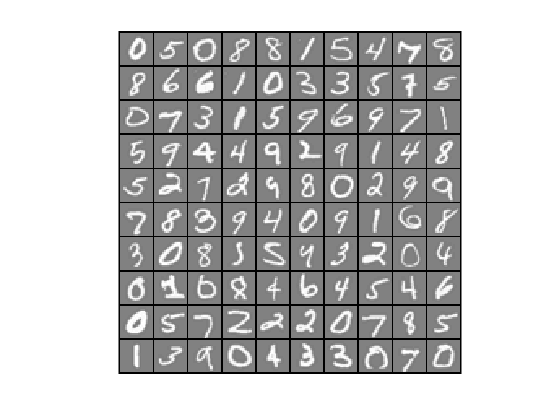


load('ex3data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
% X,y均来自ex3data1.mat
sel = randperm(size(X, 1));
sel = sel(1:100);

displayData(X(sel, :));

## ================ Part 2: Loading Pameters ================

In this part of the exercise, we load some pre-initialized neural network parameters.

fprintf('\nLoading Saved Neural Network Parameters ...\n')


Loading Saved Neural Network Parameters ...


% Load the weights into variables Theta1 and Theta2
load('ex3weights.mat');
% theta1、theta2均来自该文件

## ================= Part 3: Implement Predict =================

pred = predict(Theta1, Theta2, X);

fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 97.520000


这部分内容，使用实时脚本效果一般，无法实现.m文件那样的运行一次可以显示一张图片的效果，不能实现图片刷新的效果

%  To give you an idea of the network's output, you can also run
%  through the examples one at the a time to see what it is predicting.

%  Randomly permute examples，乱序处理1~m
rp = randperm(m);

for i = 1:m
    % Display 
    fprintf('\nDisplaying Example Image\n');
    displayData(X(rp(i), :));

    pred = predict(Theta1, Theta2, X(rp(i),:));
    fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));
    % Pause with quit option
    s = input('Paused - press enter to continue, q to exit:','s');
    if s == 'q'
      break
    end
end


Displaying Example Image



Neural Network Prediction: 9 (digit 9)



Displaying Example Image



Neural Network Prediction: 7 (digit 7)



Displaying Example Image



Neural Network Prediction: 9 (digit 9)
